%% FUNCIÓN DE TRANSFERENCIA DEL SISTEMA DE DOS TANQUES ACOPLADOS
% Este script carga los parámetros calculados previamente en:
%   parametros_tanques.mat
%
% y construye la función de transferencia:
%
%           H2(s)
% G(s) = ----------
%          Qin(s)
%
% Para tanques iguales:
%
%                  1
% G(s) = -----------------------------------
%        A^2*R1*s^2 + A*(2 + R1/R2)*s + 1/R2
%
% IMPORTANTE:
% No se usa step(G), porque la entrada es un caudal Qin en [m^3/s].
% En su lugar se usa lsim con un caudal realista.

clear; clc; close all;

%% 1) CARGAR PARÁMETROS
if ~isfile('parametros_tanques.mat')
    error(['No se encontró el archivo parametros_tanques.mat. ' ...
           'Primero ejecuta el Live Script de cálculo de R1 y R2.']);
end

load('parametros_tanques.mat');

%% 2) VERIFICAR VARIABLES NECESARIAS
if ~exist('R1','var') || ~exist('R2','var') || ~exist('A_tanque','var')
    error('Faltan variables necesarias en parametros_tanques.mat');
end

A = A_tanque;

%% 3) MOSTRAR DATOS PRINCIPALES
fprintf('============================================\n');

fprintf(' FUNCIÓN DE TRANSFERENCIA - DOS TANQUES\n');

 FUNCIÓN DE TRANSFERENCIA - DOS TANQUES


fprintf('============================================\n');

fprintf('Área del tanque A = %.6f m^2\n', A);

Área del tanque A = 0.022500 m^2


fprintf('R1 = %.6f s/m^2\n', R1);

R1 = 722.630956 s/m^2


fprintf('R2 = %.6f s/m^2\n', R2);

R2 = 1013.846545 s/m^2


fprintf('============================================\n\n');


%% 4) CONSTRUIR FUNCIÓN DE TRANSFERENCIA
num = 1;
den = [A^2*R1, A*(2 + R1/R2), 1/R2];

G = tf(num, den)


G =
 
                  1
  ----------------------------------
  0.3658 s^2 + 0.06104 s + 0.0009863
 
Continuous-time transfer function.



fprintf('Función de transferencia G(s) = H2(s)/Qin(s):\n');

Función de transferencia G(s) = H2(s)/Qin(s):


disp(G);

  tf with properties:

       Numerator: {[0 0 1]}
     Denominator: {[0.3658 0.0610 9.8634e-04]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




%% 5) DEFINIR UN CAUDAL REALISTA DE ENTRADA
% Bomba nominal de ejemplo: 240 L/h
Qmax_Lh = 240;   % [L/h]

% Conversión de L/h a m^3/s
Qmax = (Qmax_Lh / 1000) / 3600;   % [m^3/s]

% Porcentaje del caudal máximo que quieres simular
% Puedes cambiar este valor: 0.2, 0.5, 0.8, 1.0, etc.
fraccion_caudal = 0.70;   % 50% del caudal máximo

Qin_constante = fraccion_caudal * Qmax;   % [m^3/s]

fprintf('Caudal máximo asumido = %.8e m^3/s\n', Qmax);

Caudal máximo asumido = 6.66666667e-05 m^3/s


fprintf('Fracción usada        = %.2f\n', fraccion_caudal);

Fracción usada        = 0.70


fprintf('Caudal aplicado Qin   = %.8e m^3/s\n\n', Qin_constante);

Caudal aplicado Qin   = 4.66666667e-05 m^3/s



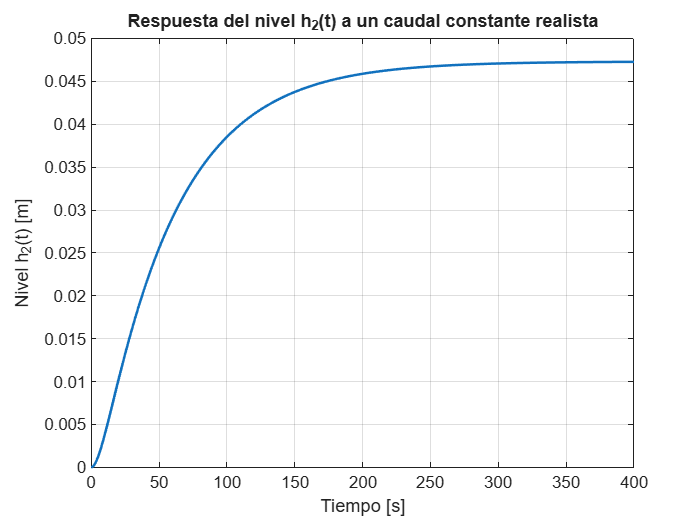


%% 6) DEFINIR TIEMPO DE SIMULACIÓN
t = 0:1:400;   % tiempo [s]

% Entrada constante de caudal
u = Qin_constante * ones(size(t));

%% 7) RESPUESTA DEL SISTEMA CON LSIM
[y, t_out] = lsim(G, u, t);

figure;
plot(t_out, y, 'LineWidth', 1.5);
grid on;
title('Respuesta del nivel h_2(t) a un caudal constante realista');
xlabel('Tiempo [s]');
ylabel('Nivel h_2(t) [m]');

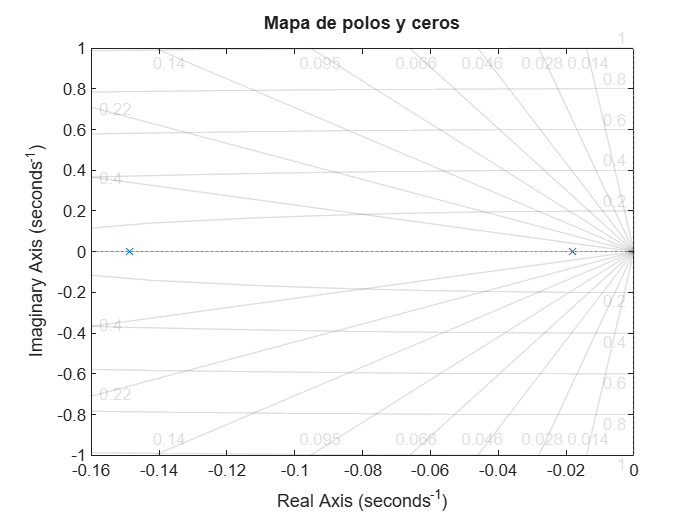


%% 8) MAPA DE POLOS Y CEROS
figure;
pzmap(G);
grid on;
title('Mapa de polos y ceros');

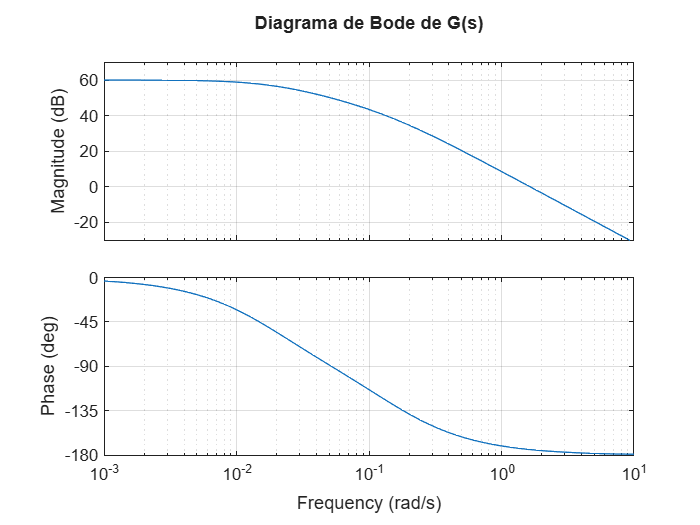


%% 9) DIAGRAMA DE BODE
figure;
bode(G);
grid on;
title('Diagrama de Bode de G(s)');

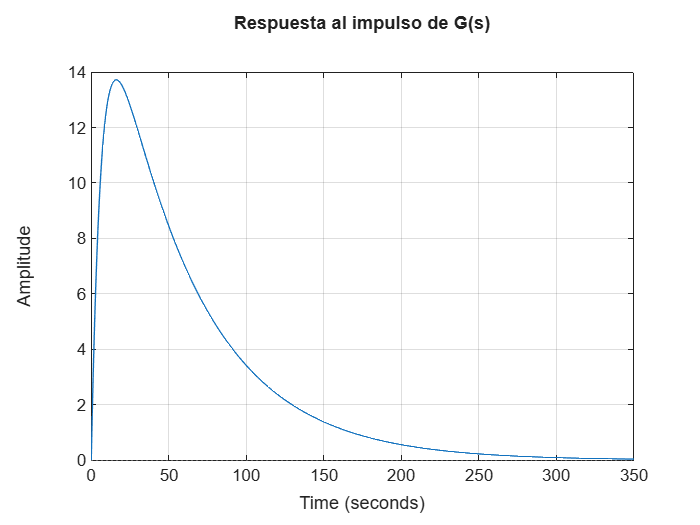


%% 10) RESPUESTA AL IMPULSO
figure;
impulse(G);
grid on;
title('Respuesta al impulso de G(s)');


%% 11) MOSTRAR ALGUNOS VALORES DE INTERÉS
nivel_final_estimado = y(end);

fprintf('Nivel final aproximado para el caudal aplicado = %.6f m\n', nivel_final_estimado);

Nivel final aproximado para el caudal aplicado = 0.047275 m


fprintf('Nivel final aproximado en cm = %.2f cm\n', nivel_final_estimado * 100);

Nivel final aproximado en cm = 4.73 cm
